# Wave Physical Modeling as PI Model

clear
close all
format compact
clc

## Simulation Params

t_stop = 30;
wd = (2*pi/0.05)/10;

## Circuit Params

A = 1;
T = 10;
pi_length = 10;

rho = 1000;
g = 9.8;
w = 2*pi/T;
c = g/w;
lambda = g*T^2/(2*pi);
P = rho*g^2/(16*w)*(2*A)^2

P = 3.8213e+04

Vrms = A*w/sqrt(2)  % deta/dt

Vrms = 0.4443

d_eta_pk = A*w;

ZC = 2*w^3/(g^2*rho)

ZC = 5.1656e-06

Cl = rho*g/(2*w^2);
Ll = 2*w^4/(rho*g^3);
z = 1i*w*Ll;
y = 1i*w*Cl;
gamma = sqrt(z*y)

gamma = 0.0000 + 0.0403i

Z = z*pi_length;
Y = y*pi_length;

expected_phase_shift = pi_length/lambda*360

expected_phase_shift = 23.0811


L_lumped = Z/(1i*w)

L_lumped = 3.3119e-06

C_lumped = Y/(1i*w)/2

C_lumped = 6.2059e+04


L = L_lumped;
C = C_lumped;
SIL = ZC;

% Corrected
% Zp = Z*sinh(gamma*pi_length)/(gamma*pi_length);
% Yp = Y*tanh(gamma*pi_length/2)/(gamma*pi_length/2);
% L = Zp/(1i*w)
% C = Yp/(1i*w)/2

## Documentation

### General Waves

wave speed = wave length / wave period = wave length * wave frequency

wave speed = sqrt(elastic property / inertial property)


$$c = \lambda f = \lambda/T=\lambda \frac{\omega}{2 \pi}$$


### Electrical

For electrical, $c = \sqrt{\frac{1}{L_l C_l}}$ where Ll and Cl are per length.  It then follows that $\frac{\lambda^2}{T^2} = \frac{1}{L_l C_l}$Considering current as the through variable and voltage as the across variable, then the elastic property is 1/Ll and the inertial property is Cl.

### Water

For water, $c = \sqrt{\frac{g \lambda}{2 \pi}}$.  It then follows that $c = \sqrt{\frac{c 2 \pi g}{2 \pi \omega}}$  and


$$c = \sqrt{\frac{g^2}{\omega^2}} = \frac{g}{\omega}$$


Considering force as the through variable and speed as the across variable, the elastic property is $g^2$ and the inertial property is $\omega^2$.  

$C_l = \omega^2$ and $L_l = \frac{1}{g^2}$

Generalizing,

$L_l = \frac{1}{kg^2}$ and $C_l =k \omega^2$.

### PI Model

A PI model is good for distances about 5% of the wavelength.  Assuming a 100 meter wavelength, that's only 5 meters.

Assume Ll and Cl are per length.

Assume z is the series impedance per unit length.  Neglecting resistance, $z = j \omega L_l$

Assume y is the shunt admittance per unit length.  Neglecting resistance, $y = j \omega C_l$


$$Z_C = \sqrt{\frac{z}{y}}$$



$$\gamma = \sqrt{yz}$$


PI model: $Z = zl$ and $Y = yl$.

The two admittances are split Y/2.  Therefore each branch capacitance is $C_l l/2$.  The series inductance is $L_l l$

To make the PI model match the true 2-port:

$Z' = Z \sinh(\gamma l)/(\gamma l)$ and $Y' = Y \tanh((\gamma l)/2)/((\gamma l) / 2)$

A PI model is valid so long as $\sinh(\gamma l) = \gamma l$ and $\tanh((\gamma l)/2) = (\gamma l) / 2$

### Set LC based on Power

For monochromatic waves, the wave power is

$P_{wave} = \frac{\rho g^2}{32 \pi} H^2 T = \frac{\rho g}{16 \pi} c H^2 =  \frac{\rho g^2}{16 \omega} H^2$ [W/m]

where $H = 2A$ and $\eta = A \sin\left(\frac{2 \pi}{T} t\right) = A \sin\left(\omega t\right)$

Assuming voltage is $\dot{\eta}$ and current is force.


$$\dot{\eta} = A \omega \cos\left(\omega t \right)$$


Then


$$\left( \frac{A \omega}{\sqrt{2}}\right)^2 / Z_c = P_{wave}$$



$$Z_c = \frac{2 \omega^3}{g^2 \rho}$$



$$Z_C = \sqrt{\frac{z}{y}} = \sqrt{\frac{L_l}{C_l}} = \frac{1}{kg\omega} = \frac{2 \omega^3}{g^2 \rho}$$


## Characteristic Impedance Taylor Expansion (Even-Order)

Express the wave characteristic impedance $Z_C(\omega )$ using even powers of ω, by expanding around ω₀ up to 4th order.

### Taylor Expansion Expression

The original impedance is:


$$Z_C(\omega) = \frac{2\omega^3}{g^2 \rho}$$


Rewriting this as a function of $\( x = \omega^2 \)$, we get:


$$Z_C(x) = \frac{2x^{3/2}}{g^2 \rho} \quad \text{where } x = \omega^2$$


The Taylor expansion of $\( x^{3/2} \)
$ around $\( x_0 = \omega_0^2 \)$ gives:


$$x^{3/2} \approx x_0^{3/2} + \frac{3}{2}x_0^{1/2}(x - x_0) + \frac{3}{8}x_0^{-1/2}(x - x_0)^2$$


Substituting back $\( x = \omega^2 \)$, we obtain:


$$Z_C(\omega) \approx A_0 + A_2 \omega^2 + A_4 \omega^4$$


### **Coefficients**

The coefficients are:


$$A_0 = -\frac{\omega_0^3}{4 g^2 \rho}
$$



$$
A_2 = \frac{3\omega_0}{2 g^2 \rho}
$$



$$
A_4 = \frac{3}{4 g^2 \rho \omega_0}$$


### Final Approximation Expression

Thus, the even-order approximation of $\( Z_C(\omega) \)$ becomes:


$$Z_C(\omega) \approx -\frac{\omega_0^3}{4 g^2 \rho} + \frac{3\omega_0}{2 g^2 \rho} \omega^2 + \frac{3}{4 g^2 \rho \omega_0} \omega^4$$


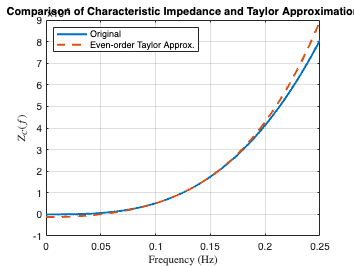

% Parameters
omega0 = 0.125 * 2*pi; % expansion point (rad/s)

% Frequency range
omega = linspace(0, 2*omega0, 500);

% Original characteristic impedance
Z_true = (2 .* omega.^3) ./ (g^2 * rho);

% Taylor expansion coefficients (even-order around omega0)
A0 = -omega0^3 / (4 * g^2 * rho);
A2 = (3 * omega0) / (2 * g^2 * rho);
A4 = 3 / (4 * g^2 * rho * omega0);

% Taylor approximation
Z_approx = A0 + A2 .* omega.^2 + A4 .* omega.^4;

% Plotting
figure
plot(omega/(2*pi), Z_true, 'LineWidth', 2)
hold on
plot(omega/(2*pi), Z_approx, '--', 'LineWidth', 2)
xlabel('Frequency (Hz)', 'Interpreter', 'latex')
ylabel('$Z_C(f)$', 'Interpreter', 'latex')
legend('Original', 'Even-order Taylor Approx.', 'Location', 'northwest')
title('Comparison of Characteristic Impedance and Taylor Approximation')
grid on
hold off


$$k = \frac{g \rho}{2 \omega^4}$$



$$L_l = \frac{1}{kg^2} = \frac{2 \omega^4}{\rho g^3}$$



$$C_l = k \omega^2 = \frac{g \rho}{2 \omega^2}$$


## Frequency Dependence


$$L_l = \frac{1}{kg^2} = \frac{2 \omega^4}{\rho g^3} = -\frac{2}{\rho g^3} s^4$$



$$C_l = k \omega^2 = \frac{g \rho}{2 \omega^2} = -\frac{g \rho}{2} \frac{1}{s^2}$$


%s = tf('s');
%G_true = -g*rho/2 / (s^2);  % True system

% Full frequency vector (rad/s)
w_full = logspace(log10(2*pi/10), log10(2*pi/1), 1000);

k = g*rho./(2*w_full.^4);
G_true = 1./(k.*g.*w_full);

% Generate frequency response with noise
% [mag_full, phase_full] = bode(G_true, w_full);
% mag_full = squeeze(mag_full);
% phase_full = squeeze(phase_full);
mag_full = abs(G_true);
phase_full = angle(G_true);

% Add measurement noise
noise_level = 0.05;
mag_noisy = mag_full .* (1 + noise_level * randn(size(mag_full)));
phase_noisy = phase_full + 2 * randn(size(phase_full));

H_full = mag_noisy .* exp(1j * phase_noisy * pi/180);

data = idfrd(H_full, w_full, 0, 'FrequencyUnit', 'rad/s');
G = tfest(data, 4)  % 2nd order model


G =
 
  -0.02027 s^3 - 0.1572 s^2 - 0.04932 s - 0.1361
  ----------------------------------------------
   s^4 + 2.433 s^3 + 81.75 s^2 + 238.7 s + 2874
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 4   Number of zeros: 3
   Number of free coefficients: 8
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                 
Estimated using TFEST on frequency response data "data".
Fit to estimation data: 93.12%                          
FPE: 6.666e-09, MSE: 6.56e-09                           
 
Model Properties


G2 = fitfrd(data,4)


G2 =
 
  A = 
           x1      x2      x3      x4
   x1  -29.25   62.47  -62.47   31.24
   x2  -36.31   70.63  -68.64   34.32
   x3  -33.43   66.86  -68.85   35.42
   x4  -29.07   58.14  -58.14   27.08
 
  B = 
           u1
   x1  0.1569
   x2  0.1953
   x3  0.1888
   x4  0.1467
 
  C = 
            x1       x2       x3       x4
   y1   0.4897  -0.9793   0.9793  -0.4897
 
  D = 
              u1
   y1  -0.002686
 
Continuous-time state-space model.


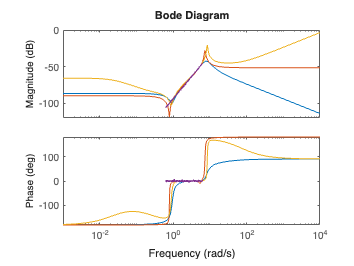


[num1, den1] = invfreqs(H_full, w_full, 4, 3);
G3 = tf(num1, den1);

bode(G,G2,G3,data)